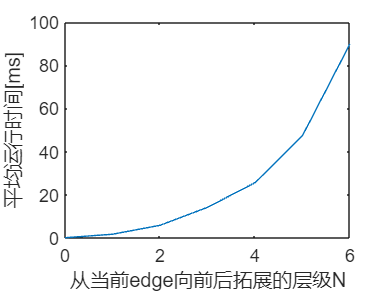

% load ProcessedMap_yizhuang.mat
% 如果没加载地图要加载一下
figureID = 1;
edgeID = '30048339#25'; % 靠近复杂交叉口的一个edge
testRunNum = 20;
testN = 6;
RuntimeResult = zeros(testRunNum,testN+1);
for i = 1:testRunNum
    for j = 0:testN
        tic;
        plotNLevelRoadNet(entity_dict,connection_dict,edgeID,j,figureID);
        RuntimeResult(i,j+1) = toc;
    end
end
RuntimeResult = mean(RuntimeResult);
plot(0:testN,RuntimeResult*1000);
xlabel('从当前edge向前后拓展的层级N')
ylabel('平均运行时间[ms]')

% 输入数据（0~6个输入）
inputs = 0:testN;

% 运行时间数据
runtime = RuntimeResult*1000;

% 拟合多项式模型（假设多项式阶数为2，即二次多项式）
p_poly = polyfit(inputs, runtime, 2);
runtime_poly_fit = polyval(p_poly, inputs);

% 拟合指数模型（形式为 a * b^x）
% 需要将数据转化为线性形式 log(runtime) = log(a) + x*log(b)
log_runtime = log(runtime);
p_exp = polyfit(inputs, log_runtime, 1);
a_exp = exp(p_exp(2));
b_exp = exp(p_exp(1));
runtime_exp_fit = a_exp * b_exp .^ inputs;

% 计算拟合优度（R平方值）
SS_res_poly = sum((runtime - runtime_poly_fit).^2);
SS_tot = sum((runtime - mean(runtime)).^2);
R2_poly = 1 - SS_res_poly / SS_tot;

SS_res_exp = sum((runtime - runtime_exp_fit).^2);
R2_exp = 1 - SS_res_exp / SS_tot;

% 显示结果
disp(['Polynomial fit R^2: ', num2str(R2_poly)]);

Polynomial fit R^2: 0.98231


disp(['Exponential fit R^2: ', num2str(R2_exp)]);

Exponential fit R^2: 0.28026



% 根据R平方值判断时间复杂度
if R2_poly > R2_exp
    disp('The runtime complexity is more likely to be polynomial.');
else
    disp('The runtime complexity is more likely to be exponential.');
end

The runtime complexity is more likely to be polynomial.


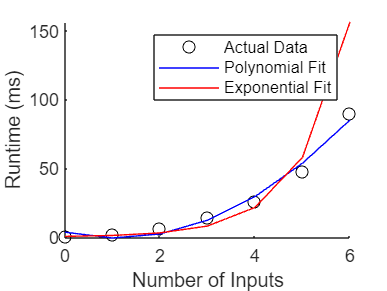


% 绘制拟合结果
figure;
hold on;
plot(inputs, runtime, 'ko', 'DisplayName', 'Actual Data');
plot(inputs, runtime_poly_fit, 'b-', 'DisplayName', 'Polynomial Fit');
plot(inputs, runtime_exp_fit, 'r-', 'DisplayName', 'Exponential Fit');
xlabel('Number of Inputs');
ylabel('Runtime (ms)');
legend;
hold off;